# 6. Image Regression

load imageRegressionData.mat

## What is Regression?

Regression is another task that can be accomplished with deep learning. *Regression* refers to assigning continuous response values to data, instead of discrete classes.

One example of image regression is correcting rotated images. The input data is a rotated image, and the known response is the angle of rotation.

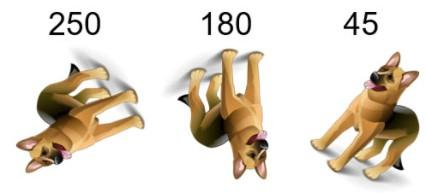

You will build a network that corrects the color in images. 

A set of images have been modified by changing their red, green, and blue channels. The response for each modified image is three numeric values that correspond to the intensity increase or decrease of the corresponding channel.

### Peek into the data

trainingData % 파일 위치, r, g, b

trainingData = 2040×2 table
                 File                       Color      
    ______________________________    _________________

    {'TrainingImages/img0001.jpg'}     18    -15    -25
    {'TrainingImages/img0002.jpg'}      5     16     -8
    {'TrainingImages/img0003.jpg'}     32     15     -1
    {'TrainingImages/img0004.jpg'}     -7    -13     14
    {'TrainingImages/img0005.jpg'}     -3    -40     -8
    {'TrainingImages/img0006.jpg'}     20    -22    -11
    {'TrainingImages/img0007.jpg'}      3      2      8
    {'TrainingImages/img0008.jpg'}     26     22      7
    {'TrainingImages/img0009.jpg'}     15    -15     -9
    {'TrainingImages/img0010.jpg'}    -14    -33     13
    {'TrainingImages/img0011.jpg'}    -41     -2     -3
    {'TrainingImages/img0012.jpg'}      0     -2    -22
    {'TrainingImages/img0013.jpg'}     -7     36     33
    {'TrainingImages/img0014.jpg'}      0     10    -22
    {'TrainingImages/img0015.jpg'}    -13     -8     46
    {'TrainingImage

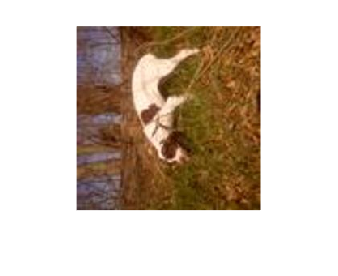

imshow(imread(trainingData.File{1})) % 셀 형태로 추출해서 디스플레이

size(imread(trainingData.File{1}))

ans =    227   227     3


## Transfer Learning for Image Regression

###     Modify the network layers for regression

- Replace the `fullyConnectedLayer` 

- Delete the softmax layer and the classification layer

- Add a `regressionLayer`

net = alexnet;
layers = net.Layers

layers =   다음 계층을 포함한 25×1 Layer 배열:

     1   'data'     영상 입력         227×227×3 영상 (정규화: 'zerocenter')
     2   'conv1'    컨벌루션          96개 11×11×3 컨벌루션(스트라이드: [4  4], 채우기: [0  0  0  0])
     3   'relu1'    ReLU             ReLU
     4   'norm1'    교차 채널 정규화    교차 채널 정규화 (요소당 채널 5개)
     5   'pool1'    최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
     6   'conv2'    그룹화된 컨벌루션   2 groups of 128 5×5×48 컨벌루션(스트라이드: [1  1], 채우기: [2  2  2  2])
     7   'relu2'    ReLU             ReLU
     8   'norm2'    교차 채널 정규화    교차 채널 정규화 (요소당 채널 5개)
     9   'pool2'    최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
    10   'conv3'    컨벌루션          384개 3×3×256 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    11   'relu3'    ReLU             ReLU
    12   'conv4'    그룹화된 컨벌루션   2 groups of 192 3×3×192 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    13   'relu4'    ReLU             ReLU
    14   'conv5'    

analyzeNetwork(net)

###     Prepare the data

trainds = augmentedImageDatastore([227,227], trainingData);
testds = augmentedImageDatastore([227,227], testData);

layers(23) = fullyConnectedLayer(3); %fully co layer % 연속된 숫자의 경우에는 2
layers(24:end) = []; % 계층 삭제
layers = [layers;regressionLayer] % 회귀출력 만들어주기 (여러번 실행 주의!)

layers =   다음 계층을 포함한 24×1 Layer 배열:

     1   'data'    영상 입력         227×227×3 영상 (정규화: 'zerocenter')
     2   'conv1'   컨벌루션          96개 11×11×3 컨벌루션(스트라이드: [4  4], 채우기: [0  0  0  0])
     3   'relu1'   ReLU             ReLU
     4   'norm1'   교차 채널 정규화    교차 채널 정규화 (요소당 채널 5개)
     5   'pool1'   최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
     6   'conv2'   그룹화된 컨벌루션   2 groups of 128 5×5×48 컨벌루션(스트라이드: [1  1], 채우기: [2  2  2  2])
     7   'relu2'   ReLU             ReLU
     8   'norm2'   교차 채널 정규화    교차 채널 정규화 (요소당 채널 5개)
     9   'pool2'   최댓값 풀링        3×3 최댓값 풀링 (스트라이드: [2  2], 채우기: [0  0  0  0])
    10   'conv3'   컨벌루션          384개 3×3×256 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    11   'relu3'   ReLU             ReLU
    12   'conv4'   그룹화된 컨벌루션   2 groups of 192 3×3×192 컨벌루션(스트라이드: [1  1], 채우기: [1  1  1  1])
    13   'relu4'   ReLU             ReLU
    14   'conv5'   그룹화된 컨벌루션   2 

## Train the Network 

단일 CPU에서 훈련합니다.
입력 데이터의 정규화를 초기화하는 중입니다.
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　Ｅｐｏｃｈ　　｜　　반복　횟수　　｜　　　　경과　시간　　　　　｜　　미니　배치　ＲＭＳＥ　　｜　　미니　배치　손실　　｜　　기본　학습률　　｜
｜　　　　　　　　　｜　　　　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　　｜　　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　　１　｜　　　　　　　１　｜　　　　　００：００：０９　｜　　　　　　　　４２．５８　｜　　　　　　９０６．６　｜　１．００００ｅ－０４　｜
｜　　　　　　　４　｜　　　　　　５０　｜　　　　　００：０３：４２　｜　　　　　　　　１０．５４　｜　　　　　　　５５．６　｜　１．００００ｅ－０４　｜
｜　　　　　　　７　｜　　　　　１００　｜　　　　　００：０７：０５　｜　　　　　　　　　８．８７　｜　　　　　　　３９．４　｜　１．００００ｅ－０４　｜
｜　　　　　　１０　｜　　　　　１５０　｜　　　　　００：１０：２２　｜　　　　　　　　　７．３０　｜　　　　　　　２６．７　｜　１．００００ｅ－０４　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
훈련 완료: 최대 Epoch가 완료되었습니다.


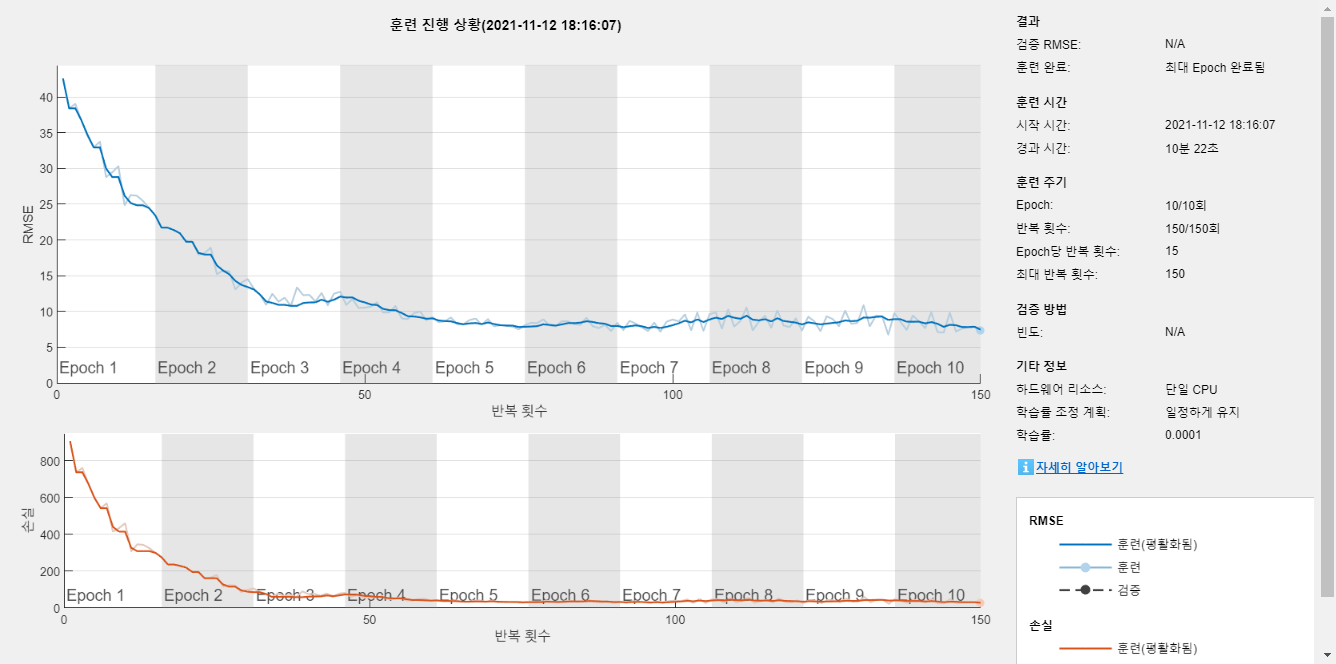

newNet =   SeriesNetwork - 속성 있음:

         Layers: [24×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'regressionoutput'}


% 빛 바랜 이미지 복구, 화질 개선 등에 이미지 regression이 사용 됨.
options = trainingOptions("adam","MaxEpochs",10,"InitialLearnRate",0.0001,...
    "Plots","training-progress");

newNet = trainNetwork(trainds,layers,options)


% 평소에는 val 데이터 추가해서 어디까지 에폭 설정해도 되는지 모니터링하면서 파라미터 수정할 것.

## Evaluate the Network

Predict the response for all images in the test data and calculate the root mean squre error (RMSE) for the test data set.

testPred = predict(newNet, testds);
rgbGT = testData.Color;
err = rgbGT - testPred;
rmse = sqrt(mean(err.^2))





## Correct the color

Use the network to correct the rgb value of the first test image and display the corrected image.

imageNum = 1;

다음 사용 중 오류가 발생함: imread>get_full_filename (569번 라인)
파일 "testImage"이(가) 존재하지 않습니다.

오류 발생: imread (371번 라인)
    fullname = get_full_filename(filename);


testImage = imread( testData.File{imageNum})
imshow(testImage)

%첨부된 함수 사용
rgb = testPred(imageNum,:) %첫 번째 이미지의 예측값
correctedImage = correctColor(testImage,rgb) % rgb 업데이트 (색 보정)
imshow(correctedImage)